% x' = Ax + Bu
% y = Cx + Du
A = [-1.5 -2; 1 0];
B = [0.5;0];
C = [0 1];
D = 0;

s_space = ss(A, B, C, D)

s_space =
 
  A = 
         x1    x2
   x1  -1.5    -2
   x2     1     0
 
  B = 
        u1
   x1  0.5
   x2    0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



[n, d] = ss2tf(A,B,C,D)

n =          0         0    0.5000


d =     1.0000    1.5000    2.0000


G = tf(n, d)

G =
 
        0.5
  ---------------
  s^2 + 1.5 s + 2
 
Continuous-time transfer function.



[n, d] = tfdata(G)

n = 1×1 cell array
    {[0 0 0.5000]}


d = 1×1 cell array
    {[1 1.5000 2.0000]}


[A, B, C, D] = tf2ss(n{1}, d{1})

A =    -1.5000   -2.0000
    1.0000         0


B =      1
     0


C =          0    0.5000


D = 0

% C*((sI - A)^-1)*B + D 
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = C * inv(s*eye(2) - A)*B + D

G =
 
        0.5
  ---------------
  s^2 + 1.5 s + 2
 
Continuous-time transfer function.



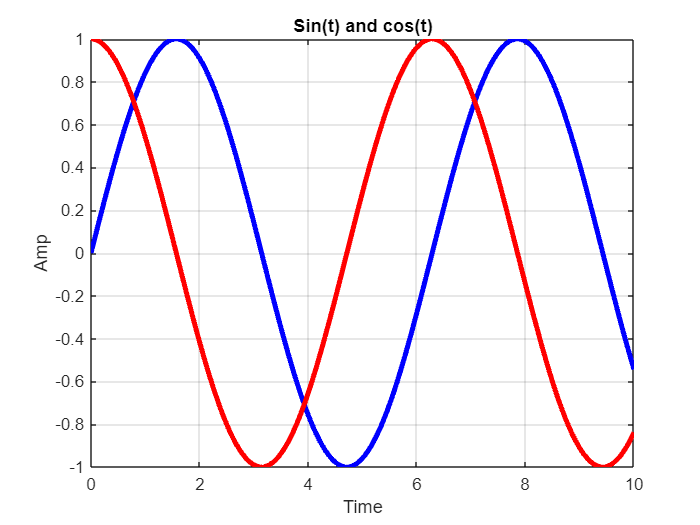

% plots
t = 0:0.01:10;
x = sin(t);
y = cos(t);
plot(t, x, 'b', t, y, 'r', 'LineWidth', 3)
title('Sin(t) and cos(t)')
xlabel('Time')
ylabel('Amp')
grid on

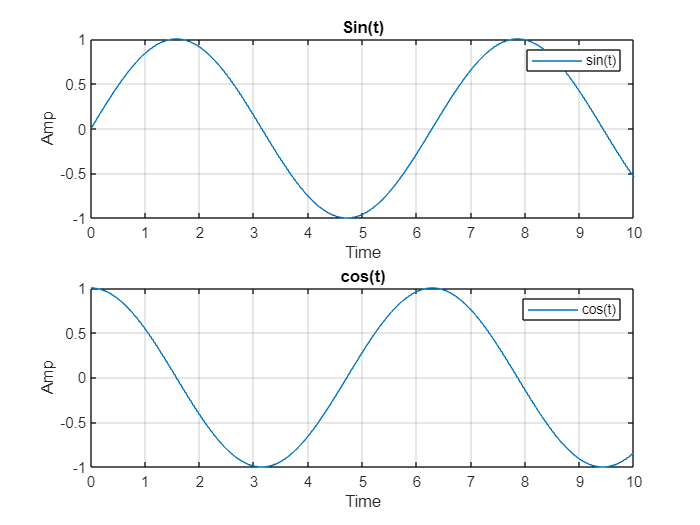

% subplots
t = 0:0.01:10;
x = sin(t);
y = cos(t);

figure(1);
subplot(211);
plot(t, x)
title('Sin(t)')
xlabel('Time')
ylabel('Amp')
grid on
legend('sin(t)')
subplot(212);
plot(t, y)
title('cos(t)')
xlabel('Time')
ylabel('Amp')
grid on
legend('cos(t)')